# MPEG Audio Project - Part B

## MPEG Audio Encoder Layer 2

clear; clc; close all;

### Reading the PCM-coded digital audio

        The sampled audio signal is read in "audio" and its sampling frequency is "fs" using audioread built-in function. The signal and its frequency spectrum is plotted as well.

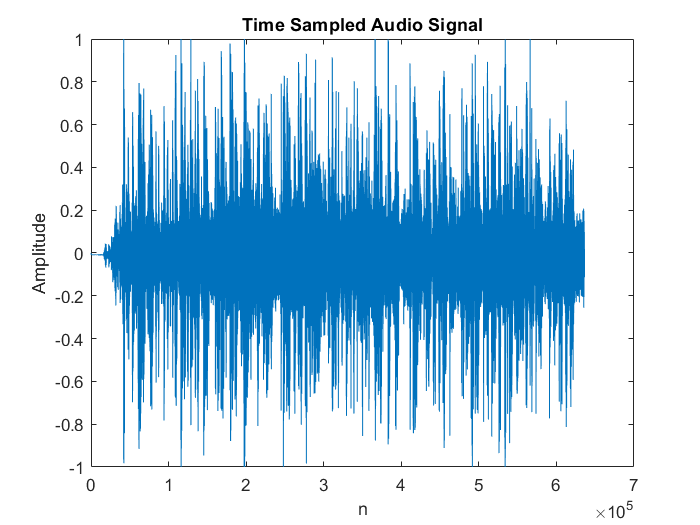

[audio fs] = audioread('listen-to-the-ancient-egyptions-tv.wav');

N = 1:length(audio);
freq = linspace(0,fs,length(audio));
%Plotting the audio signal and its Spectral View
plot(N,audio')
title('Time Sampled Audio Signal'); xlabel('n'); ylabel('Amplitude')

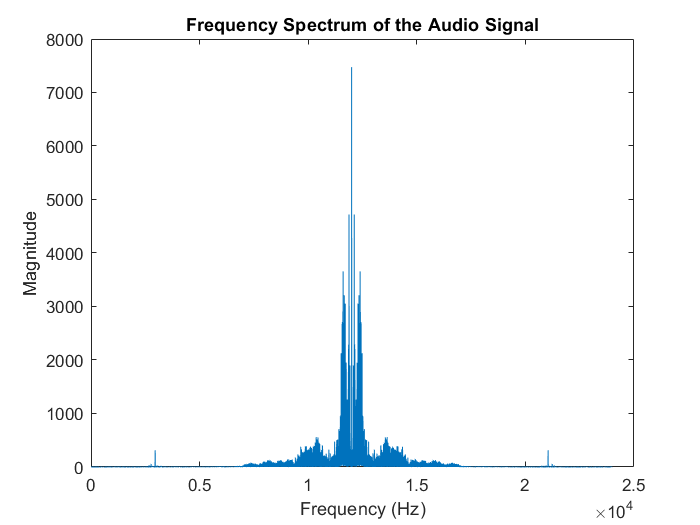

plot(freq, abs(fftshift(fft(audio'))))
title('Frequency Spectrum of the Audio Signal'); xlabel('Frequency (Hz)'); ylabel('Magnitude');

### Time-to-frequency Mapping and Filter Bank

    It aims to divide the signal into 32 frequency sub-bands. the MPEG PQMF filter coeefficients are written in "FilterCoefficients.txt".

#### Taking h[n] coefficients from the text file

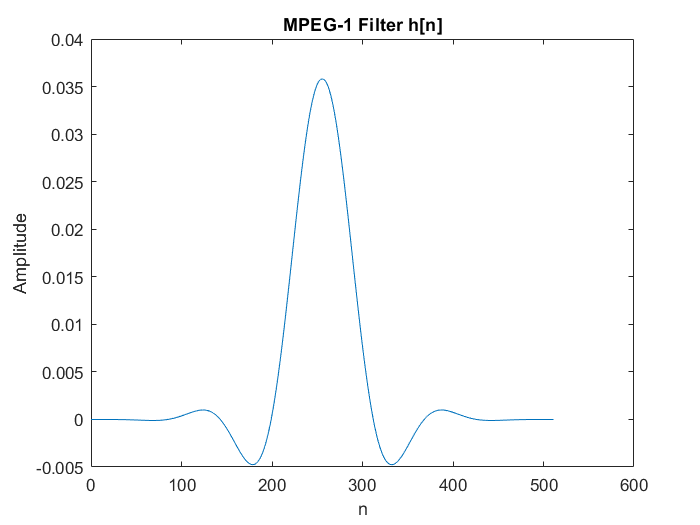

hneg = fileread('Filter Coefficients.txt');
format long;
hneg = str2num(hneg);
clear format;
hpos = flip(hneg);
h = [hneg' hpos']; %Applying the mirror to get the full time response of the filter
h = h(2:length(h)-1);
n = 0:length(h)-1; 
%Plotting the time and frequency response of the filter
plot(n,h);
title('MPEG-1 Filter h[n]'); xlabel('n'); ylabel('Amplitude');

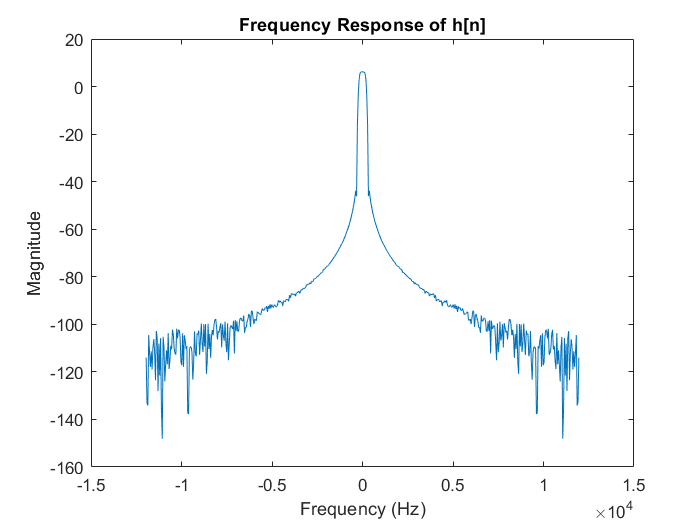

f = -fs/2:fs/512:fs/2-fs/512;
plot(f,mag2db(abs(fftshift(fft(h)))));
title('Frequency Response of h[n]'); xlabel('Frequency (Hz)'); ylabel('Magnitude');

#### Getting the 32 filter bank hk[n] and its inverse gk[n]

where

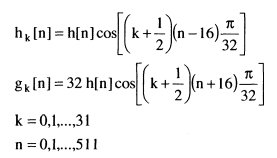

The frequency responses of the filters are plotted. Also, the each filter of the 32 is applied on the signal producing 32 signals one in each band saved in array "filteredSignal".

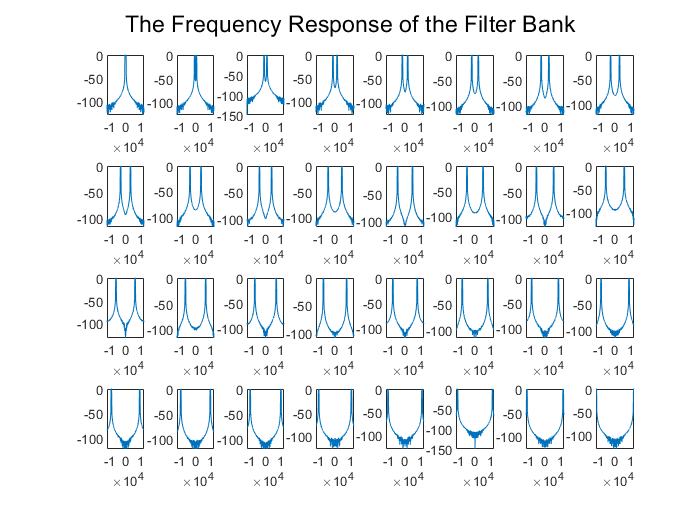

K = 1:32;

hk = []; gk = []; filteredSignal = [];
% Putting the signal into the filter bank and dividing it into 32 sub-bands
figure()
for i = K
    hk(i,:) = h.*cos((i-1+1/2)*(n-16)*pi/32); % The time response of each filter in the filter bank
    subplot(4,8,i) % Plotting the 32 filters' frequency responses
    plot(f,mag2db(abs(fftshift(fft(hk(i,:))))))
    %xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
    filteredSignal(i,:) = filter(hk(i,:),1,audio); % Filtering the audio with each filter in the filter bank
    gk(i,:) = 32*h.*cos((i-1+1/2)*(n+16)*pi/32); % Getting the inverse of each filter
end
sgtitle('The Frequency Response of the Filter Bank');

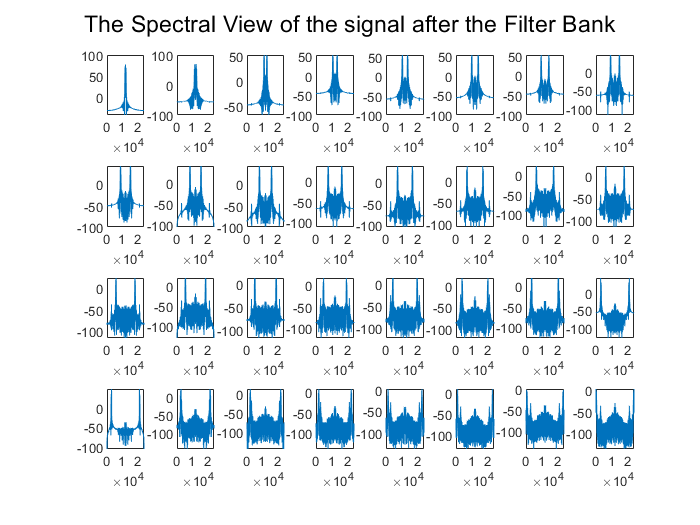

% Plotting The spectral view of the output signals of the filter bank
figure()
for i = K
    subplot(4,8,i)
    plot(freq,mag2db(abs(fftshift(fft(filteredSignal(i,:))))))
    %xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
end
sgtitle('The Spectral View of the signal after the Filter Bank');

### The Down Sampler 

To avoid increasing the bit rate by having number of samples equal to the number of samples of the original signal multiplied by 32, down sampling is used to decrease the number of samples produced from each filter so that the overall number of samples equals the number of samples of the original signal. The 32 down sampled signals are saved in "downSampledSignal". Moreover, the spectral view of the output of the down sampler is plotted.

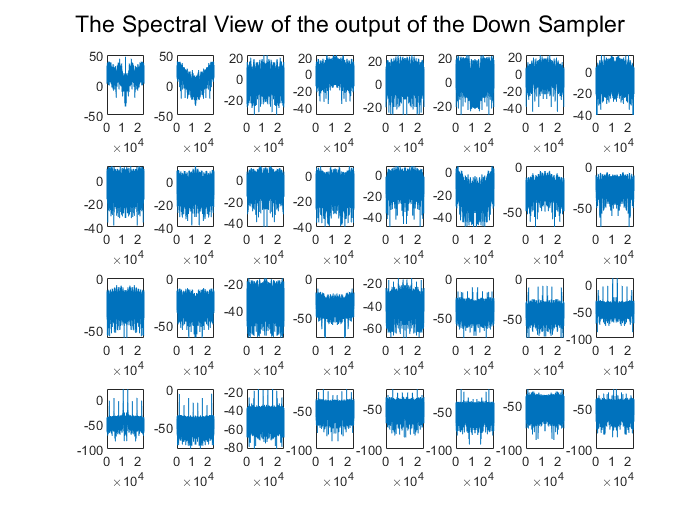

% The down sampled 32 signals after the filterbank
downSampledSignal = [];
for i = K
    downSampledSignal(i,:) = downsample(filteredSignal(i,:),length(K)); 
end
freqdown = linspace(0,fs,length(downSampledSignal(1,:)));
% Plotting the spectral view of the output of the down sampler.
figure()
for i = K
    subplot(4,8,i)
    plot(freqdown,mag2db(abs(fftshift(fft(downSampledSignal(i,:))))))
    %xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
end
sgtitle('The Spectral View of the output of the Down Sampler')

## **Psychoacoustic model implementation:**

Reading the audio file using the built-in function **audioread** and plotting the time domain audio signal.

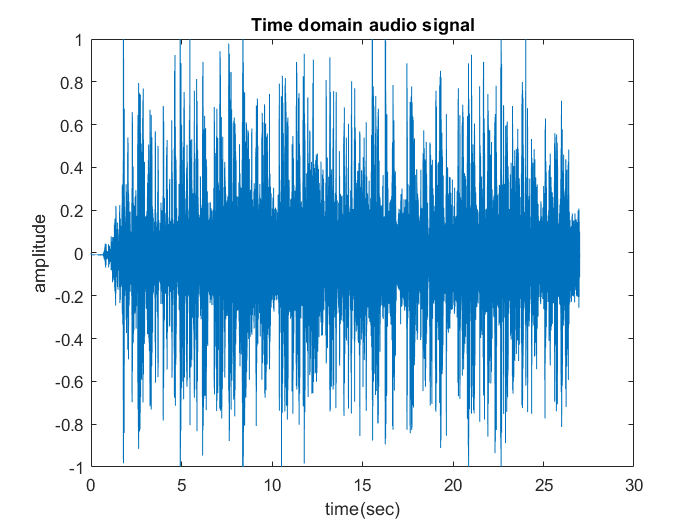

N = 1024;

FD_signal=zeros(1,N);      
t=0:27/(length(audio)-1):27;
figure;
plot(t,audio);
title('Time domain audio signal');
xlabel('time(sec)');
ylabel('amplitude');

**Time to frequency mapping:**

Generating the frequency spectrum of the signal after applying the han window of length 1024 withe overlapping between windows equals 64 (N/16).

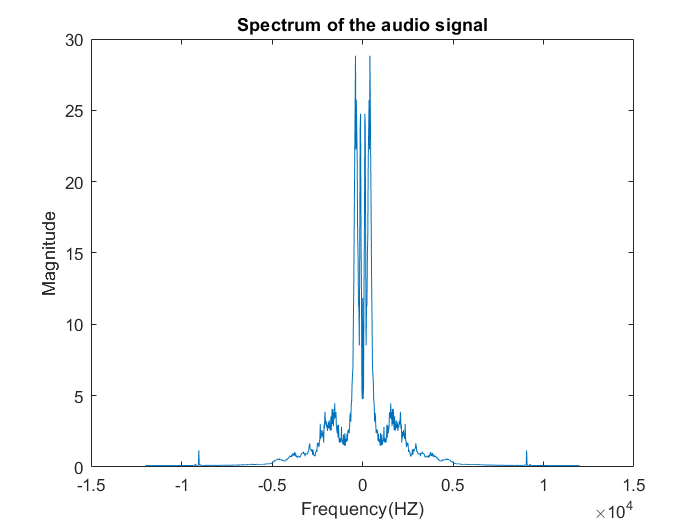


v=[];
counter=0;
index=1;

while(index <= length(audio))
if(index <= length(audio)-1024)
   
windowed_sig = audio(index:index+1024-1);
FD_signal = FD_signal+ abs(fftshift(fft(windowed_sig, N)))';

else  
z = audio(index:end);             
v(1:length(z)) = z;
v(length(z)+1:1024) = 0;
windowed_sig = v; 
FD_signal = FD_signal + abs(fftshift(fft(windowed_sig,N)));
end
counter = counter+1;
index = index+1024-64;
end
FD_signal = FD_signal./counter;
f = linspace(-fs/2,fs/2,length(FD_signal));

figure;
plot(f,FD_signal);
title('Spectrum of the audio signal');
xlabel('Frequency(HZ)');
ylabel('Magnitude');

**Calculating the thereshold of hearing and and SPLs using the follwoing equations:**

**Threshold of hearing computation:**


$$\textrm{threshold}\left(f\right)=3\ldotp 64\;{\left(\frac{f}{1000}\right)}^{-0\ldotp 8} -\;6\ldotp 5\;e^{-0\ldotp 6{\left(\frac{f}{1000-3\ldotp 3}\right)}^2 } +{10}^{-3} \;{\left(\frac{f}{1000}\right)}^4$$


**SPL computation:**

After applying the FFT, the signal level is computed for each spectral line $K$, $L_k$ as follows


$$L_k =96\;\textrm{dB}+10{\;\log }_{10} \left(\frac{4}{N^2 }\;{\left|X\left\lbrack K\right\rbrack \right|}^2 \;\frac{8}{3}\right)\;\textrm{for}\;K=0,\ldotp \ldotp \ldotp \ldotp \ldotp ,\frac{N}{2}-1$$


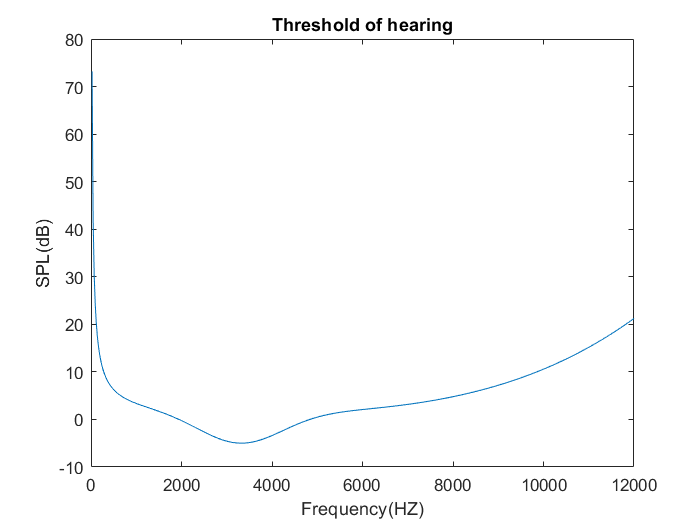


f_new = linspace(0,fs/2,512);             
Threshold_of_hearing=[];

for i=1:length(f_new)
Threshold_of_hearing(i) = 3.64*((f_new(i)/1000)^(-0.8)) - 6.5*exp(-0.6*((f_new(i)/1000-3.3)^2)) + 10^-3*(f_new(i)/1000)^4;
end
figure;
plot(f_new,Threshold_of_hearing)
title('Threshold of hearing');
xlabel('Frequency(HZ)');
ylabel('SPL(dB)');

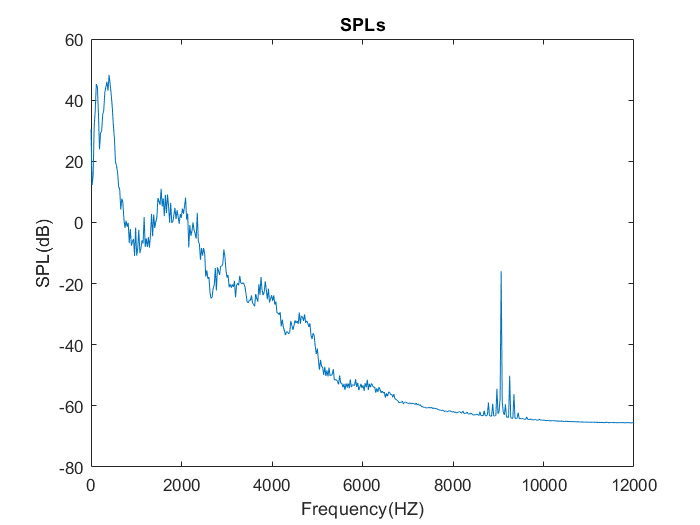

for i = 0:1:(N/2)-1
L(i+1) = 96+10*log(8/3*(4/N^2)*abs(FD_signal(i+1+N/2))^2);    
end

figure;
plot(f_new,L)
title('SPLs');
xlabel('Frequency(HZ)');
ylabel('SPL(dB)');

Dividing the frequency spectrum into 32 subbands.

f_subbands=[];
for i=1:32
f_subbands = [f_subbands f_new(i*16)];
end

**Masking:**

applying the masking of the threshold of hearing and the masking of frequencies ranging from (300-3300) which is the normal range of the human's speech.

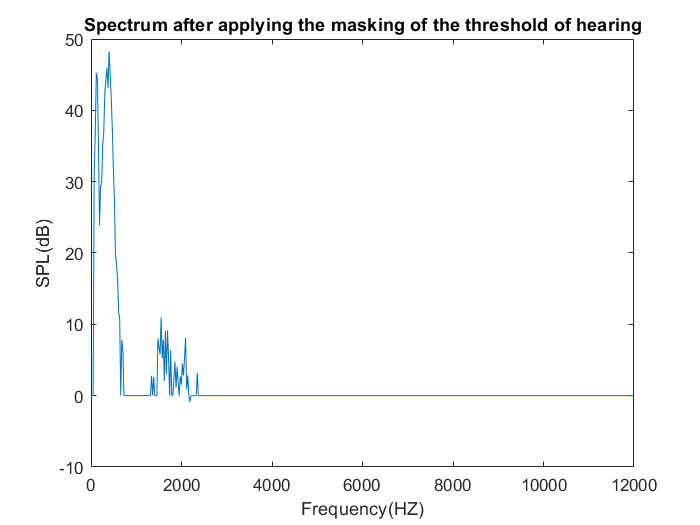

for r=1:length(L)
 if(L(r) <= Threshold_of_hearing(r)) 
  L(r) = 0;                               
 end
end

figure;
plot(f_new,L)
title('Spectrum after applying the masking of the threshold of hearing');
xlabel('Frequency(HZ)');
ylabel('SPL(dB)');

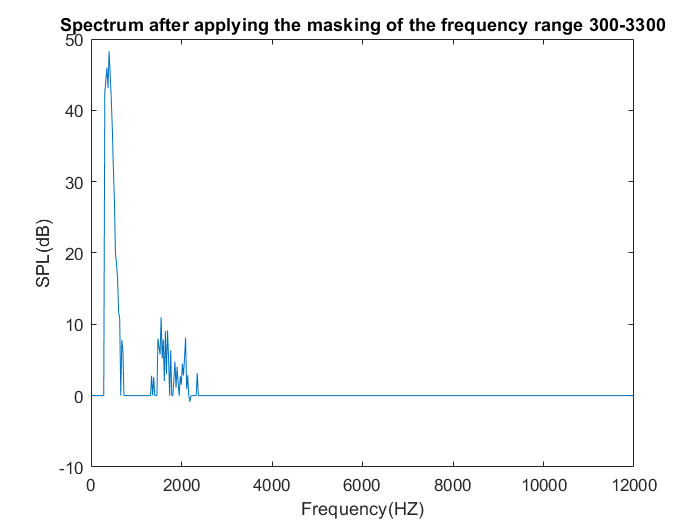


for r=1:length(L)
 if(f_new(r)<300 | f_new(r)>3300)
  L(r) = 0;
 end
end
figure;
plot(f_new,L)
title('Spectrum after applying the masking of the frequency range 300-3300');
xlabel('Frequency(HZ)');
ylabel('SPL(dB)');

 Summing the frequency components of each subband and adding these summations in the vector subbands_sum which represents how significant the band is in the used audio signal. This vector is then sent to the bit allocation block to use for encoding and quantizing.

subbands_sum = [];       
for k = 0:length(f_subbands)-1
    subbands_sum(k+1)=sum(L(k*16+1:(k+1)*16));
end

acs = subbands_sum;

## **Bit Allocation and Coding:**

## **I. Reading the sub-band signals and Bit Allocation:**

        The first step is done by reading the Filter Bank output, the sub-band signals, and mapping the Psychoacoustic model's output (SMR values) onto it by assigning bit allocations based on the SMR values. 

    in=downSampledSignal; %filter bank output
    SMR=acs; %psychoacoustic model output
    c=36-rem(length(in),36);
    in=[in zeros(32,c)]; %padding the signal with zeros to have equally sized frames
    
    maxbits=16; %maximum bits per sample is 16 as determined by the audio file
    allocbits=bitallocator(SMR,maxbits);
   
    %using the SMR values to assign bit allocation values using our designed function
    disp('bit allocation values: ')

bit allocation values: 


    disp(allocbits)

  Columns 1 through 24

     6    16     0     1     4     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 25 through 32

     0     0     0     0     0     0     0     0



## **II. Constructing Layer II Frames, Encoding and Quantizing**

    Ths sub-band signals are divided into frames of equal size where each frame consists of 3 granule, each granule has 12 samples producing a total of 36 samples per each sub-band in each frame.

    This is followed by Quantization and Encoding of the each frame using a uniform quantizer (quantizator function) shifted and scaled with every frame row (sub-band) so that the minimum value for each frame row is the minimum quantization level and the maximum level of each frame row is the maximum quantization level and the output of the function is the mapped level number for each sample which is then converted to binary value using the number of bits allocated. 

    The minimum and maximum values of each sub-band samples along with the number of bits allocated for that sub-band are added to each frame after encoding as additional data that is necessary for the decoding process. The output bitstream is then ready to be sent to the decoder.

    cvec=36*ones(1,length(in)/36); 
    rvec=32;
    blocks=mat2cell(in,rvec,cvec);%creating a cell array where each cell is a frame
    encodedblocks=cell(size(blocks));%cell array of encoded frames
    minmax=zeros(32,2);
    encodedframe=zeros(32,3+36*max(allocbits));
    for i=1:length(blocks)
        frame=zeros(32,36+2);
        frame(:,1:36)=cell2mat(blocks(i));%assigning a row of 36 samples to a framee
        for j=1:32
            minmax(j,1)=min(frame(j,:));%calculating the min value sample in each frame row
            minmax(j,2)=max(frame(j,:));%calculating the max value sample in each frame row
        end
        frame(:,37:38)=minmax;%appending the min and max values for the frame to the frame itself
        for k=1:32
            r=frame(k,:);%frame row
            [q_r, q_r_levels]=quantizator(r(1:36),2^allocbits(k)); %quantization of frame row samples 
            encodedframe(k,[1 2])=frame(k,[37 38]);
            encodedframe(k,3)=allocbits(k);
            if allocbits(k)~=0 %only encode if bit allocation is more than zero
                q_r_bi=reshape(fliplr(de2bi(q_r,allocbits(k)))',1, allocbits(k)*36); %converting to bit stream
                encodedframe(k,4:4+length(q_r_bi)-1)=q_r_bi;
            end
        end
        encodedblocks(i)=num2cell(encodedframe,[1 2]);
    end
    yout=cell2mat(encodedblocks);%output bitstream

## MPEG Audio Decoder Layer 2

## **Frequency Samples Reconstruction:**

Decoding the Bitstream back into the quantized values representing the original signal using the dequantization function (dequantizator) and formatting them as a matrix of 32 subbands each with coefficients in the frequency domain. The output of this block will be ready for frequency to time mapping to finally reconstruct the audio signal.

    in_bits=yout; %encoded bitstream
    maxbits=max(allocbits); %max allowed limit of bit allocations
    r=32; c=(36*maxbits+3)*ones(1,length(in_bits)/(36*maxbits+3));
    bits_blocks=mat2cell(in_bits,r,c);%creating a cell array of bit frames
    decoded_blocks=cell(size(bits_blocks));%decoded cell array creation
    bits_frame=zeros(32,36*maxbits+3);
    for l=1:length(bits_blocks)
        bits_frame=zeros(32,36*maxbits+3);
        bits_frame=cell2mat(bits_blocks(l));
        frame_out=zeros(32,36);
        for h=1:32
            minn=bits_frame(h,1);
            maxx=bits_frame(h,2);
            nobits=bits_frame(h,3); %decoding the bit frame using the bit allocation number
            if nobits~=0            %max value and min value for each bit frame row
                frame_out(h,:)=dequantiztor(bits_frame(h,4:36*nobits+3),2^nobits,minn,maxx);
            end
        end
        decoded_blocks(l)=num2cell(frame_out,[1 2]);
    end
    ydec_out=cell2mat(decoded_blocks); %reverting bricks to the original stream

### The Up Sampler and Inverse Filter Bank:

To reconstruct the audio signal, upsampling should be used in addition to applying an inverse filter bank to the 32 sub-bands. The reconstructed signal spectral view is plotted.

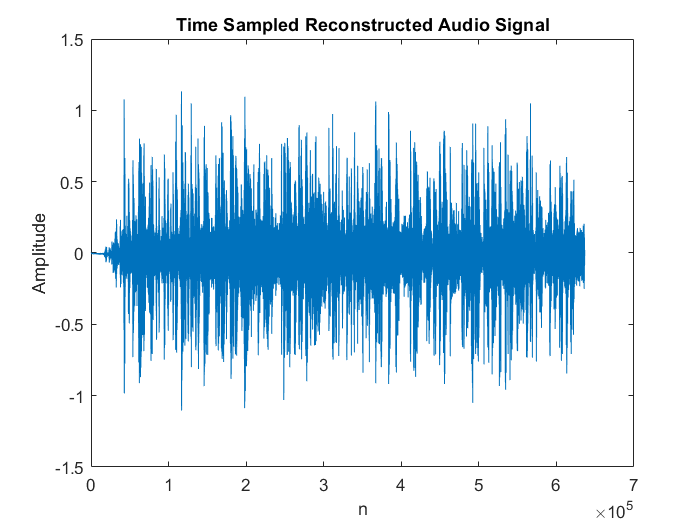

%ydec_out=cell2mat(struct2cell(load('DECODED F-DOMAIN.mat')));
[r,c] = size(ydec_out);
upSampledSignal = []; reconstructedSignal = zeros(1,c*length(K));
for i = K
    upSampledSignal(i,:) = upsample(ydec_out(i,:),length(K)); % Upsampling the Dequantized Signal
    reconstructedSignal = reconstructedSignal + filter(gk(i,:),1,upSampledSignal(i,:)); % Applying the inverse of the filter bank
end
% Plotting the Reconstructed Signal (Time and Frequency)
figure()
plot(1:length(reconstructedSignal),reconstructedSignal);
title('Time Sampled Reconstructed Audio Signal'); xlabel('n'); ylabel('Amplitude')

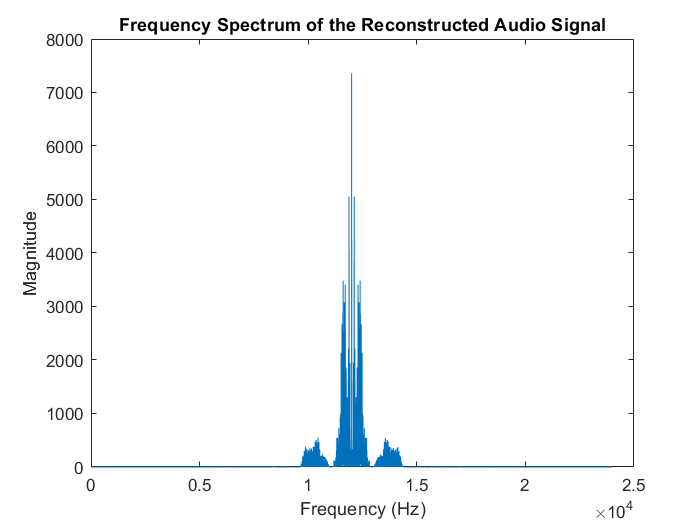

freq_rec = linspace(0,fs,length(reconstructedSignal));
plot(freq_rec, abs(fftshift(fft(reconstructedSignal))))
title('Frequency Spectrum of the Reconstructed Audio Signal'); xlabel('Frequency (Hz)'); ylabel('Magnitude');

% Generating the Received Audio File
audiowrite('Decoded Audio.wav',reconstructedSignal,fs);

## **Performance Measure:**

    The compression ratio is calculated by dividing the uncompressed signal by the compressed signal. This can be done in a simillar manner using the BPS (bits/sample) of the given audio signal and the average number of bits allocated for the sub-band signals, by dividing both numbers we should get the same compression ratio.

info=audioinfo('listen-to-the-ancient-egyptions-tv.wav');
info=struct2cell(info);
bps=cell2mat(info(10)); %reading BPS of the audio signal
CR=bps/mean(allocbits);
disp('Compression Ratio: ')

Compression Ratio: 


disp(CR)

  17.655172413793103



## **Perceptual Evaluation of Audio Quality:**

The used function works only on sampling frequency = 48 kHz. So we had to resample the original and the reconstructed audio signals from 24 kHz to 48 kHz so that we can use the function and obtain the odg score.

[P,Q] = rat(48e3/fs);
resampledInputSignal = resample(audio,P,Q);
resampledReconstructedSignal = resample(reconstructedSignal,P,Q);
audiowrite("resampledOutput.wav",reconstructedSignal,48e3);
audiowrite("resampledInput.wav",audio,48e3);
[odg, movb] = PQevalAudio_fn('resampledInput.wav', 'resampledOutput.wav');

 WAVE file: resampledInput.wav
   Number of samples : 636244 (13.26 s)
   Sampling frequency: 48000
   Number of channels: 1 (16-bit integer)
 WAVE file: resampledOutput.wav
   Number of samples : 637056 (13.27 s)
   Sampling frequency: 48000
   Number of channels: 1 (16-bit integer)
>>> Number of samples differ
>>> Number of samples differ: using the minimum
PEAQ Data Boundaries: 8 (0.000 s) - 636243 (13.255 s)


disp(odg);

  -3.666672781514280



Based on the odg calculated the reconstructed audio is considered to be annoying relative to the original auido. However the mean opinion score based on audience evaluation is close to 4 (preceptible but not annoying)